# sample adjust

clear;
% file = "me.wav";
file = "../audio/violin_c.wav";
[X,Fs] = audioread(file);
X = X(:, 1);
% X = X(4000:18000-1);
% X = X(1:end);
T = 1 / Fs;
L = length(X);
t = (0:L-1)*T;

size(X)

ans =       119543           1


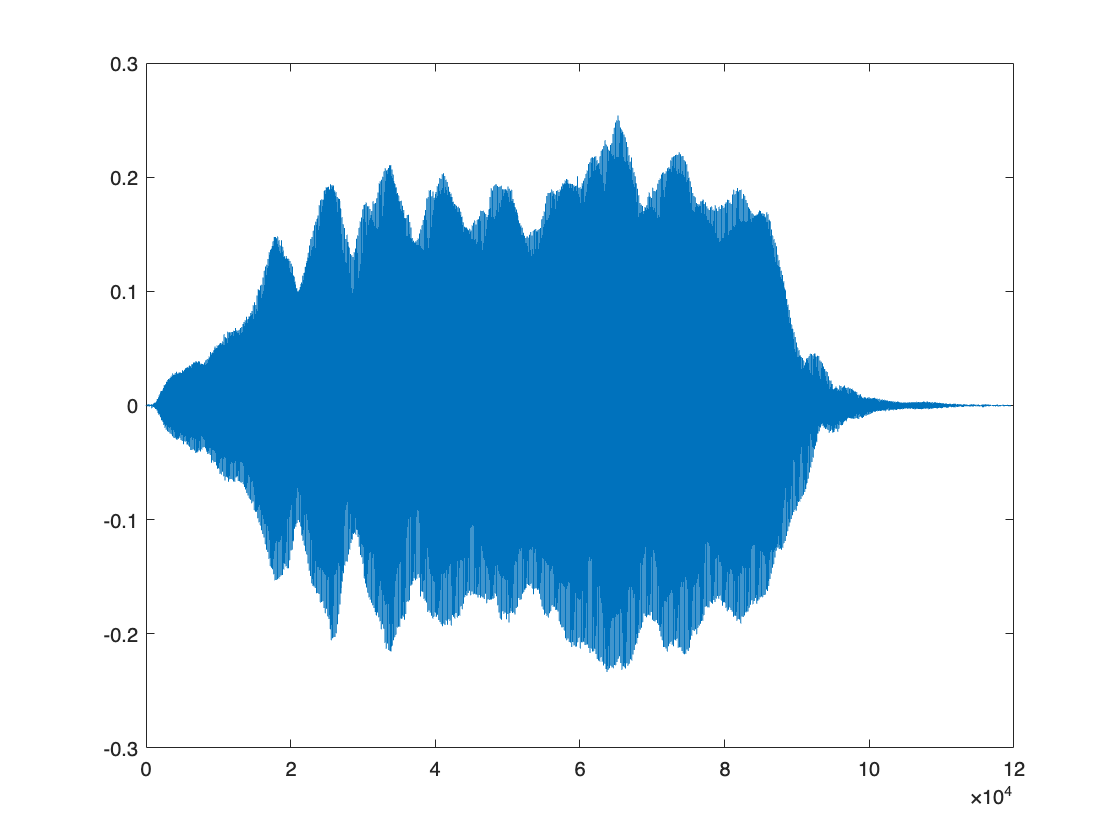

plot(Fs*t,X)

% return

% xlim([0 end])

Compute the Fourier transform of the signal. 

Y = fft(X);

Y = 1 + zeros(L, 1);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);

P1(2:end-1) = 2*P1(2:end-1);
P1_a = angle(Y);
P1_a = P1_a(1:L/2+1);

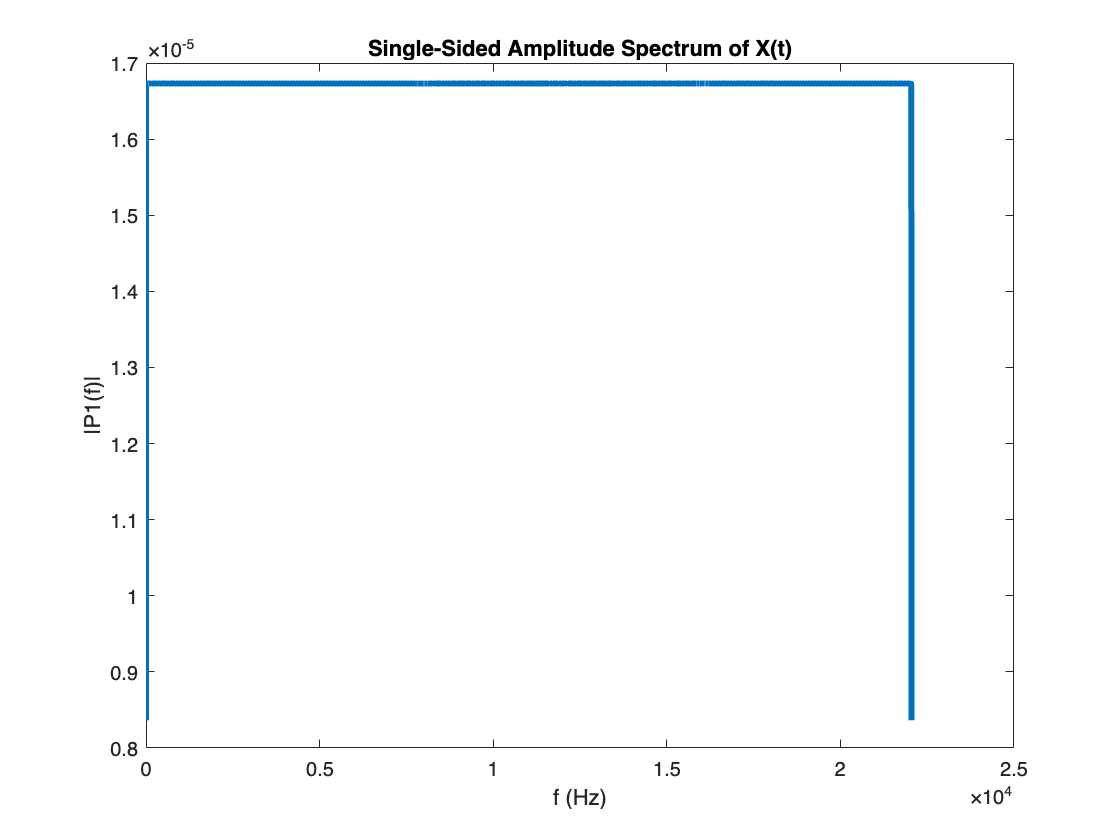

f = Fs/L*(0:(L/2));
plot(f,P1, "LineWidth",3) 
title("Single-Sided Amplitude Spectrum of X(t)")
xlabel("f (Hz)")
ylabel("|P1(f)|")

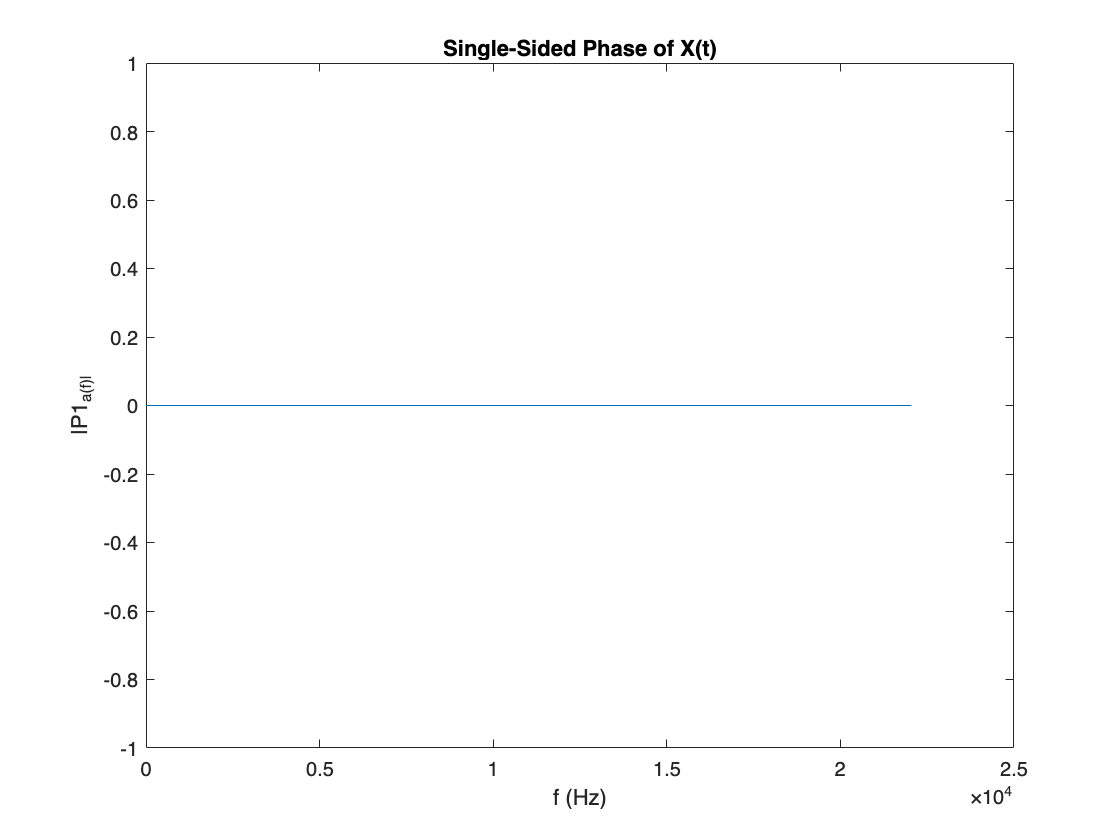

% xlim([0 2000])
% sort(P1, 'descend');
f = Fs/L*(0:(L/2));
plot(f,P1_a) %"LineWidth",3) 
title("Single-Sided Phase of X(t)")
xlabel("f (Hz)")
ylabel("|P1_a(f)|")

% Y = Y .* multiplier(linspace(0,1,L).');

P2 = abs(Y/L);
P1 = P2(1:L/2+1);

P1(2:end-1) = 2*P1(2:end-1);
P1_a = angle(Y);
P1_a = P1_a(1:L/2+1);

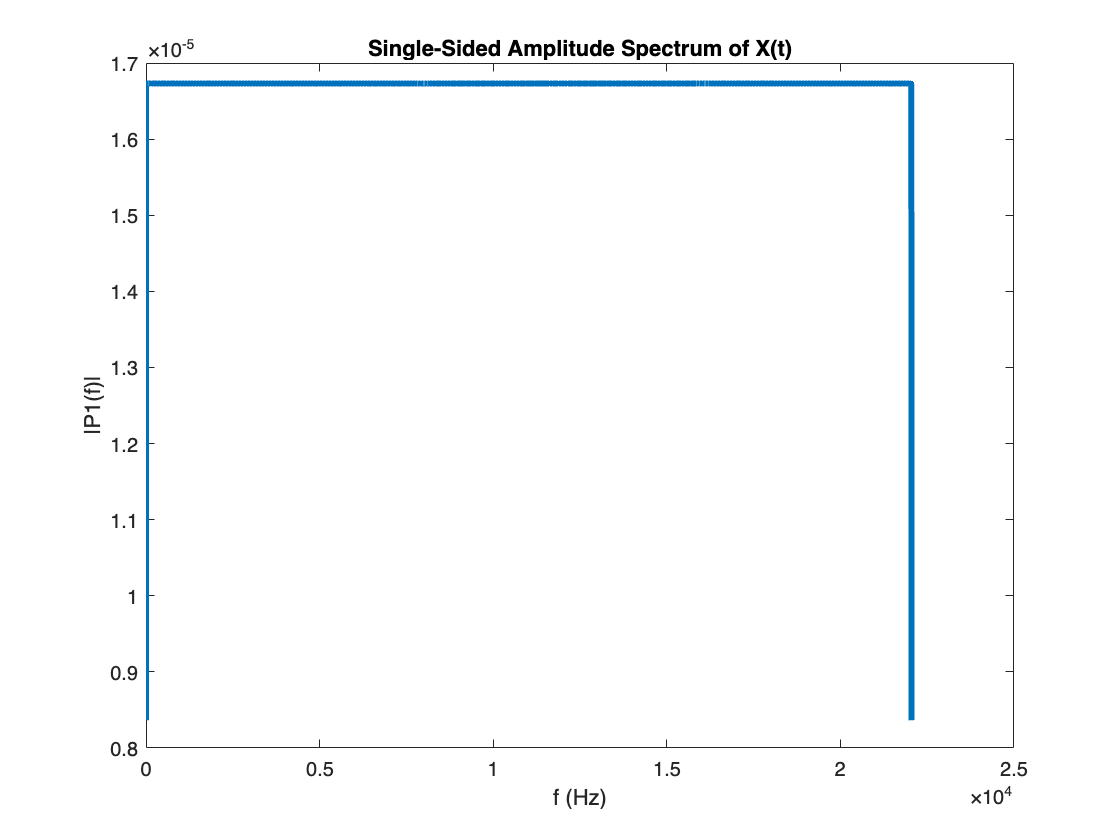

f = Fs/L*(0:(L/2));
plot(f,P1, "LineWidth",3) 
title("Single-Sided Amplitude Spectrum of X(t)")
xlabel("f (Hz)")
ylabel("|P1(f)|")

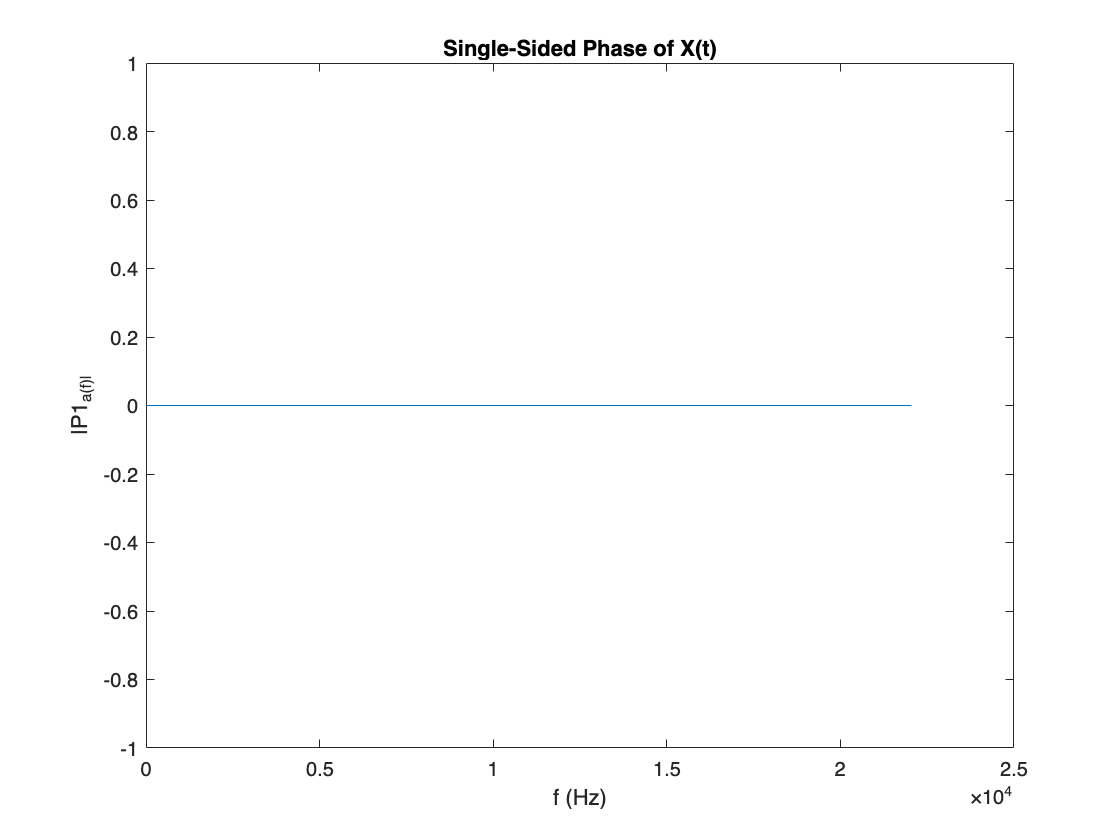

f = Fs/L*(0:(L/2));
plot(f,P1_a) %"LineWidth",3) 
title("Single-Sided Phase of X(t)")
xlabel("f (Hz)")
ylabel("|P1_a(f)|")

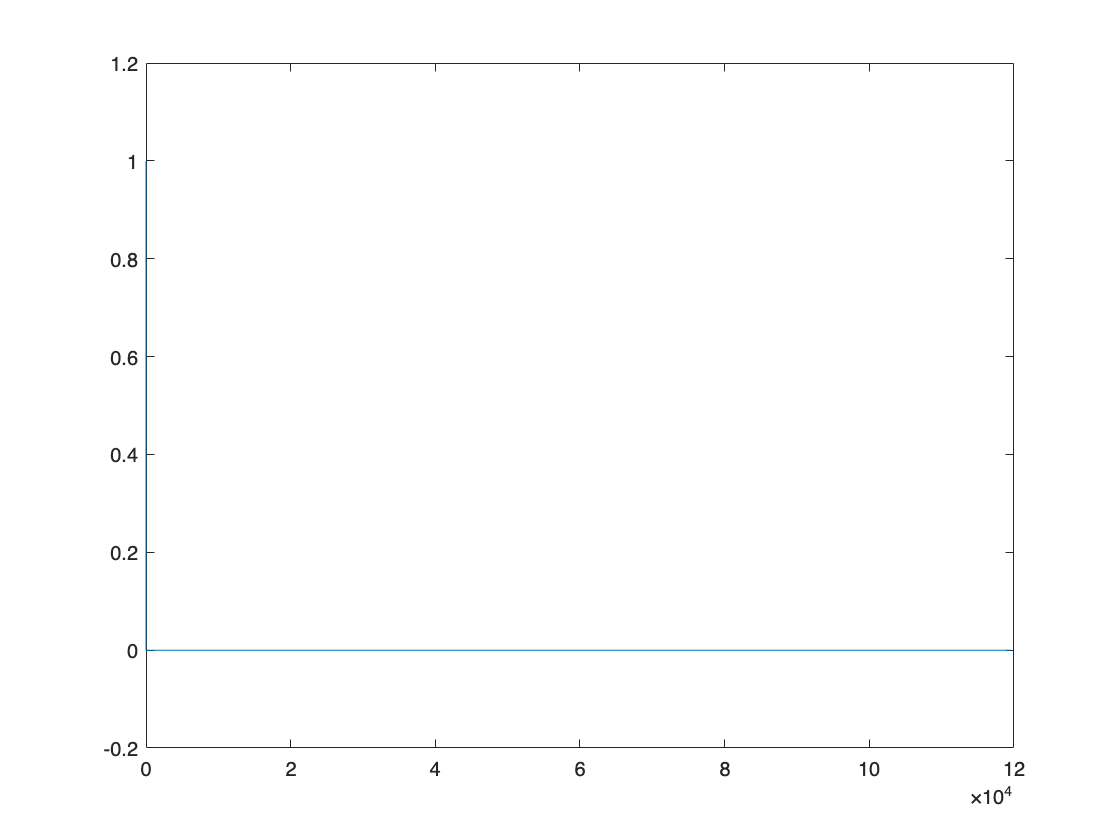


% xlim([0 5630])

freqFactor = 1.0;
dataTrashFactor = 1.0;

recs = zeros([1, L]);
for i = 0:(L/2/dataTrashFactor) % L/2
    mag = abs(Y(i+1));
    phase = angle(Y(i+1));
    add = 2*mag/L * cos(2*pi*t*Fs/L*i * freqFactor + 1*phase);
    if i == 0 || i == L/2
        add = add / 2;
    end
    recs = recs + add;
end
plot(Fs*t,recs);

round(L/dataTrashFactor)

ans = 119543



% recs - X.';

% recs =  (1*abs(Y(1))/8)*cos(0*pi*t + angle(Y(1))) + ...
%         (2*abs(Y(2))/8)*cos(2*pi*t + angle(Y(2))) + ...
%         (2*abs(Y(3))/8)*cos(4*pi*t + angle(Y(3))) + ...
%         (2*abs(Y(4))/8)*cos(6*pi*t + angle(Y(4))) + ...
%         (1*abs(Y(5))/8)*cos(8*pi*t + angle(Y(5)));
% plot(Fs*t,recs)

recs = recs / max(recs);

audiowrite("recr.wav",recs,Fs)

function m = multiplier(freqScaled)
    m = exp((freqScaled-1));
end